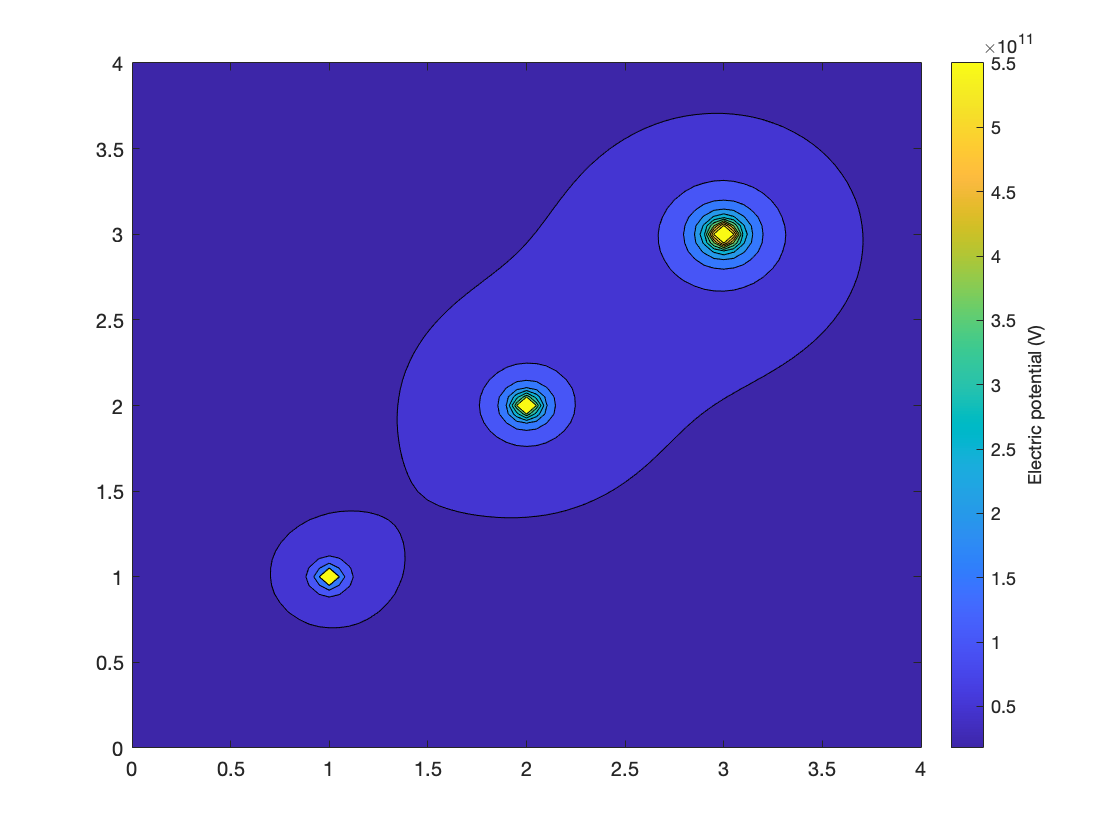

k = 8.987E9; % Coulomb's constant
p = [1,1; 2,2; 3,3];
Q = [1; 2; 3];
[X,Y] = meshgrid(0:0.05:4); % Create a grid of coordinates where V is to be calculated

V = zeros(size(X)); % Start with zero electric potential
for ii = 1:numel(Q) % Superpose the electric potential field of each charge
    V = V + k * Q(ii) ./ hypot(p(ii,1)-X, p(ii,2)-Y);
end

hContour = contourf(X,Y,V);
hColorbar = colorbar;
ylabel(hColorbar,'Electric potential (V)')

hContour.LevelList = [0 quantile(V(:),10)];

Unable to perform assignment because dot indexing is not supported for variables of this type.

[Ex,Ey] = -gradient(V);
validColumns = all(isfinite(Ex) & isfinite(Ey)); % Ignore columns where E contains infinite values due to the point charges since streamslice can't handle them
hold on
hLines = streamslice(X(:,validColumns),Y(:,validColumns),Ex(:,validColumns),Ey(:,validColumns));
set(hLines,'Color','r');
